# 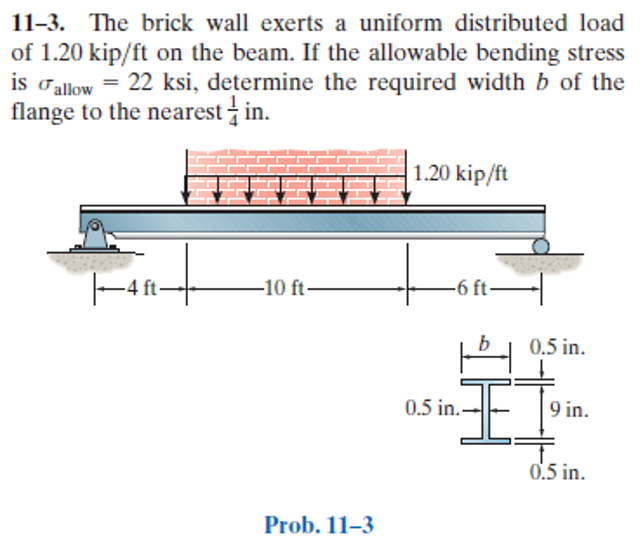

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-3P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-3P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 20*u.ft);
b = b.add('distributed', 'force', -1.20*u.kip/u.ft, [4 14]*u.ft);
b.L = 20*u.ft;

# section properties

B = sym('B');
yc = [4.75 0 -4.75]*u.in;
Ac(B) = [B*0.5*u.in 0.5*9*u.in^2 B*0.5*u.in];
Ic(B) = [B*0.5^3*u.in^3 0.5*9^3*u.in^4 B*0.5^3*u.in^3]/12;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.ft);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{912384\,x\,\left(254\,{\mathrm{ft}}^{2}-x^{2}\right)}{5\,\text{E}\,\left(2168\,B+243\,\mathrm{ft}\right)}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{3}} & \text{ if }x\leq 4\,\mathrm{ft}\\ -\frac{41472\,\left(x^{4}-38\,x^{3}\,\mathrm{ft}+96\,x^{2}\,{\mathrm{ft}}^{2}+5332\,x\,{\mathrm{ft}}^{3}+256\,{\mathrm{ft}}^{4}\right)}{5\,\text{E}\,\left(2168\,B+243\,\mathrm{ft}\right)}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{4}} & \text{ if }x\in \left(4\,\mathrm{ft},14\,\mathrm{ft}\right]\\ -\frac{746496\,\left(x-20\,\mathrm{ft}\right)\,\left(x^{2}-40\,x\,\mathrm{ft}+106\,{\mathrm{ft}}^{2}\right)}{5\,\text{E}\,\left(2168\,B+243\,\mathrm{ft}\right)}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{3}} & \text{ if }14\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{912384\,\left(254\,{\mathrm{ft}}^{2}-3\,x^{2}\right)}{5\,\text{E}\,\left(2168\,B+243\,\mathrm{ft}\right)}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{3}} & \text{ if }x\leq 4\,\mathrm{ft}\\ -\frac{82944\,\left(2\,x^{3}-57\,x^{2}\,\mathrm{ft}+96\,x\,{\mathrm{ft}}^{2}+2666\,{\mathrm{ft}}^{3}\right)}{5\,\text{E}\,\left(2168\,B+243\,\mathrm{ft}\right)}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{4}} & \text{ if }x\in \left(4\,\mathrm{ft},14\,\mathrm{ft}\right]\\ -\frac{2239488\,\left(x^{2}-40\,x\,\mathrm{ft}+302\,{\mathrm{ft}}^{2}\right)}{5\,\text{E}\,\left(2168\,B+243\,\mathrm{ft}\right)}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{3}} & \text{ if }14\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{33\,x}{5}\,\mathrm{kip} & \text{ if }x<4\,\mathrm{ft}\\ -\frac{3\,\left(x^{2}-19\,x\,\mathrm{ft}+16\,{\mathrm{ft}}^{2}\right)}{5}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\in \left[4\,\mathrm{ft},14\,\mathrm{ft}\right]\\ -\frac{27\,\left(x-20\,\mathrm{ft}\right)}{5}\,\mathrm{kip} & \text{ if }14\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{33}{5}\,\mathrm{kip} & \text{ if }x<4\,\mathrm{ft}\\ -\frac{3\,\left(2\,x-19\,\mathrm{ft}\right)}{5}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\in \left[4\,\mathrm{ft},14\,\mathrm{ft}\right]\\ -\frac{27}{5}\,\mathrm{kip} & \text{ if }14\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<4\,\mathrm{ft}\\ -\frac{6}{5}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\in \left[4\,\mathrm{ft},14\,\mathrm{ft}\right]\\ 0 & \text{ if }14\,\mathrm{ft}<x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 6.6\,\mathrm{kip}\\ \mathrm{Rb} & 5.4\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

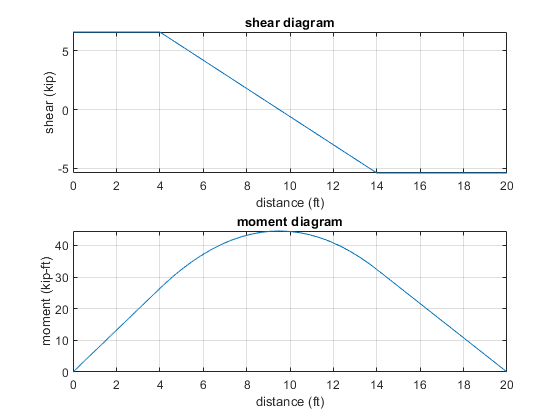

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# maximum bending moment

x_max = solve(v == 0);
M_max = m(x_max);
M_max_vpa = vpa(M_max) %#ok<NASGU> 

$$M\_max\_vpa = 44.55\,\mathrm{ft}\,\mathrm{kip}$$

# maxminum bending stress

C = 5*u.in;
b.I = simplify(rewrite(b.I, u.in));
sigma_max = rewrite(M_max*C/b.I, [u.ksi u.in])

$$sigma\_max(B) = \frac{64152}{542\,B+729\,\mathrm{in}}\,\mathrm{in}\,\mathrm{ksi}$$

# minimum beam width

sigma_allow = 22*u.ksi;
B_min = solve(sigma_max == sigma_allow);
B_min_vpa = vpa(B_min, 3) %#ok<NASGU> 

$$B\_min\_vpa = 4.04\,\mathrm{in}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;
clear M_max_vpa;
clear B_min_vpa;